clear

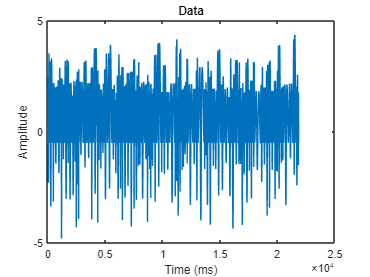

%% generate data
Fs   = 1000;
data = [];
for i = 1:10
    data = [data sim_beta_event_rand(Fs)];
end
figure, plot(data); title('Data')
xlabel('Time (ms)'); ylabel('Amplitude')

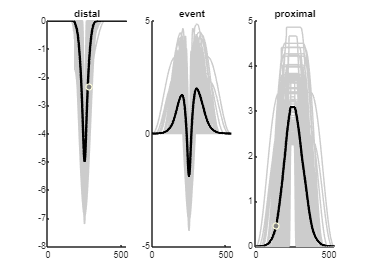


%% find extrema
trs  = find(islocalmin(data)); 
pks  = find(islocalmax(data));
n_tr = length(trs); n_pk = length(pks);

%% segment individual events
% create event counter and track last event end index
evt_i = 1; last_end = 1;
for i_t = 1:2:n_tr
    tr = trs(i_t);
    % find distal drive boundaries: surrounding peaks
    last_pk = max(pks(pks < tr));
    next_pk = min(pks(pks > tr));

    % find event boundaries
    if i_t + 1 <= n_tr 
        % if there is another trough, that ends this event
        evt_end = trs(i_t+1);
    else
        % otherwise, the event ends at the end of the data 
        evt_end = length(data);
    end
    evt = data(last_end:evt_end) - data(last_end);
    % separate laminar drive
    dist = zeros(1,length(evt));
    dist(last_pk-last_end+1:next_pk-last_end+1) = data(last_pk:next_pk);
    dist(dist~=0) = dist(dist~=0) - max(dist);
    prox = evt - dist;
    
    % save data to structs & update counter
    evts(evt_i).event     = evt;
    evts(evt_i).distal    = dist;
    evts(evt_i).proximal  = prox;
    evts(evt_i).dist_pk_i = tr-last_end+1;
    evt_i = evt_i + 1; last_end = evt_end;
end
drives = setdiff(fieldnames(evts),{'dist_pk_i'});
n_dr   = length(drives);
n_evt  = length(evts);

% center all data around distal peak
max_pk_i = max([evts(:).dist_pk_i]);
for i_e = 1:n_evt
    ph_lag = max_pk_i - evts(i_e).dist_pk_i;
    for i_d = 1:n_dr
        dr = drives{i_d};
        evts(i_e).(dr) = zero_pad(evts(i_e).(dr),ph_lag,ph_lag);
    end
end

%% plot outputs
figure
for i_d = 1:n_dr
    drive = drives{i_d}; 
    subplot(1,n_dr,i_d); hold on
    title(drive)
    for i_e = 1:n_evt
        plot(evts(i_e).(drive),'Color','#ccc')
    end
    all_evts = padcat(evts(:).(drive));
    mean_evt = mean(all_evts,1,'omitnan');
    plot(mean_evt,'LineWidth',2,'Color','#000')
end


% TODO: compute measures
    % laminar durations/freqs, amplitudes, peak latencies